% Presetting
syms x y z omega phi psi;
PosExtract=[0; 0; 0; 1];
p(x, y, z)=[x; y; z];
Rotx(omega)=[1  0   0
            0   cos(omega)  -sin(omega)
            0   sin(omega)  cos(omega)];
Roty(phi)=[cos(phi) 0   sin(phi)
            0   1   0
            -sin(phi)   0   cos(phi)];
Rotz(psi)=[cos(psi) -sin(psi)   0
            sin(psi)    cos(psi)    0
            0   0   1];

% 2-DoF Manipulator Forward Kinematics
syms L1 L2 theta1 theta2;

% Base to Arm
angle12=theta1;
p12=p(L1*cos(theta1), L1*sin(theta1), 0);
Rot12=Rotz(angle12);
T12=HomogeneousTransform(Rot12, p12, 1);

% Arm to Endpoint
angle23=theta2;
p23=p(L2*cos(theta2), L2*sin(theta2), 0);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1);

%Base to Endpoint
T13=T12*T23

$$T13 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & L_{1}\,\cos\left(\theta_{1}\right)+L_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-L_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & L_{1}\,\sin\left(\theta_{1}\right)+L_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+L_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{3}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$


% Position of Endpoint according to Base Coordinate
p13=T13*PosExtract

$$p13 = \left(\begin{array}{c} L_{1}\,\cos\left(\theta_{1}\right)+L_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-L_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ L_{1}\,\sin\left(\theta_{1}\right)+L_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+L_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0\\ 1 \end{array}\right)$$

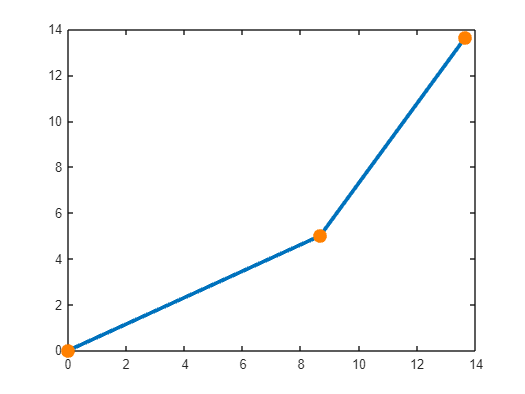

p =   Line - 속성 있음:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: [1 0.5000 0]
              XData: [0 8.6603 13.6603]
              YData: [0 5 13.6603]

  모든 속성 표시


%  2-DoF Manipulator Kinematics test by plot graph
theta1=pi/6;
theta2=pi/6;
L1=10;
L2=10;

% Base to Arm
angle12=theta1;
p12=p(L1*cos(theta1), L1*sin(theta1), 0);
Rot12=Rotz(angle12);
T12=HomogeneousTransform(Rot12, p12, 1);

% Arm to Endpoint
angle23=theta2;
p23=p(L2*cos(theta2), L2*sin(theta2), 0);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1);

%Base to Endpoint
T13=T12*T23;

% Position of Endpoint according to Base Coordinate
p13=T13*PosExtract;

% plot
p = plot([PosExtract(1,1), p12(1,1), p13(1,1)],[PosExtract(2,1), p12(2,1), p13(2,1)],'-o','LineWidth',3);
p.MarkerFaceColor = [1 0.5 0];
p.MarkerSize = 8;
p.MarkerEdgeColor = [1 0.5 0]